% SGN-26006 Advanced signal processing laboratory (2019)
%
% Assignment: Characterizing Holographic Displays
% Instructor: Jani Mäkinen
%
% Main function

clearvars

## Parameters

lambda  = 534e-9; % green wavelength
eye_loc = [0, 2e-2]; % location of the simulated eye [x,z], by default set for near-eye applications
D_eye   = 5e-3; % pupil size (default 5 mm)

% Note the definition of z (negative z_f -> eye focused behind the hologram)
z_f = -400e-3; % z coordinate where the eye is focused

methods_all = {'Fresnel', 'RS', 'HS'}; % Hologram synthesis methods
method = methods_all{2}; % choose method (1 to 3)

% Hologram plane parameters
X_x = 2e-6; % pixel size (2µm)
N   = 2^13; % number of pixels
W_x = N*X_x; % physical size (of hologram)

## Hologram plane

% Hologram plane (decentered) grid
x_max = X_x*N/2;
x = -x_max:X_x:x_max-X_x; % location of each hologram sample (x)
z_c = 0; % z location of the hologram

% HS parameters
seg_size_px = 64; % segment size in pixels
seg_size = seg_size_px*X_x; % segment physical size
x_c_ar = X_x*seg_size_px*(-(N/seg_size_px-1)/2:(N/seg_size_px-1)/2); % grid of the segment centers
num_seg = length(x_c_ar);

## Input object (the point source)

% Note the definition of z (negative z_p -> point behind the hologram)
z_p = -400e-3; % point position in z (400 mm behind the hologram)
x_p = 0;
a_p = 1; % point amplitude
phi_p = 0; % relative phase

## Check hologram size and sampling

if (0-z_p)/(eye_loc(2)-z_p)*D_eye > W_x
    warning('Hologram size is too small')
end

if lambda*eye_loc(2)/X_x/2 < abs(eye_loc(1))+D_eye/2
    warning('Hologram sampling is too coarse')
end

## Synthesize the hologram

% Initialize the fields with zeros
obj_in = zeros(1,N);
% Spherical illumination
spherical_illum = exp(1j*2*pi/lambda*sqrt((x-eye_loc(1)).^2+(z_c-eye_loc(2)).^2));
spherical_illum_comp = exp(-1j*2*pi/lambda*sqrt((x-eye_loc(1)).^2+(z_c-eye_loc(2)).^2));

if z_p==0
    % Special case, point at hologram plane
    obj_in(N/2)=a_p*exp(1i*phi_p);
else
    % Choose the hologram synthesis method
    switch method
        case 'Fresnel'
            % ADD YOUR CODE HERE
            for ii=1:num_seg
                z = z_c-z_p;
                k = (2*pi)/lambda;
                x_c = x_c_ar(ii);
                seg_ind_x = round(x_c/X_x+N/2)-seg_size_px/2+1:round(x_c/X_x+N/2)+seg_size_px/2;
                seg_x = x(seg_ind_x); % pixels x coordinates of the hogel
                obj_in(seg_ind_x) = obj_in(seg_ind_x) + ...
                    a_p * exp(1j * k * z)/(sqrt(1j * lambda * z)) * ...
                    exp(1j * k * ((seg_x-x_p).^2)/(2*z)+phi_p);
            end
            
            obj_in = obj_in.*spherical_illum_comp; % for the spherical illumination, do not remove!
        case 'RS'
            % ADD YOUR CODE HERE
            for ii=1:num_seg
                z = z_c-z_p;
                k = (2*pi)/lambda;
                x_c = x_c_ar(ii);

                seg_ind_x = round(x_c/X_x+N/2)-seg_size_px/2+1:round(x_c/X_x+N/2)+seg_size_px/2;
                seg_x = x(seg_ind_x); % pixels x coordinates of the hogel

                obj_in(seg_ind_x) = obj_in(seg_ind_x) + ...
                    a_p * ((z)./(sqrt(1j * lambda) .* ((seg_x-x_p).^2 + z.^2)).^(3/4)) ...
                    .* exp(1j*k * sqrt((seg_x-x_p).^2+z.^2) + phi_p);
            end
            
            obj_in = obj_in.*spherical_illum_comp; % for the spherical illumination, do not remove!
        case 'HS'
            for ii=1:num_seg
                % hogel = holographic element
                x_c = x_c_ar(ii); % hogel center coordinate
                
                seg_ind_x = round(x_c/X_x+N/2)-seg_size_px/2+1:round(x_c/X_x+N/2)+seg_size_px/2;
                seg_x = x(seg_ind_x); % pixels x coordinates of the hogel
                
                ang_p_x_c = atand((x_c-x_p)./(z_c-z_p)); % angle between the point and hogel center
                f_x = sind(ang_p_x_c)/lambda; % spatial frequency
                
                r_p = sqrt((x_c-x_p).^2+(z_c-z_p)^2); % Euclidean distance between the point source and the hogel center
                spherical_illum_seg = exp(-1j*2*pi/lambda*sqrt((seg_x-...
                    eye_loc(1)).^2+(z_c-eye_loc(2)).^2));
                
                % calculate field inside the current hogel
                obj_in(seg_ind_x) = obj_in(seg_ind_x) + ...
                    a_p/r_p*exp(1i*2*pi*(f_x*(seg_x-x_c))+phi_p)...
                    .*spherical_illum_seg;
            end
    end
end

## Run the simulation to obtain the retinal image

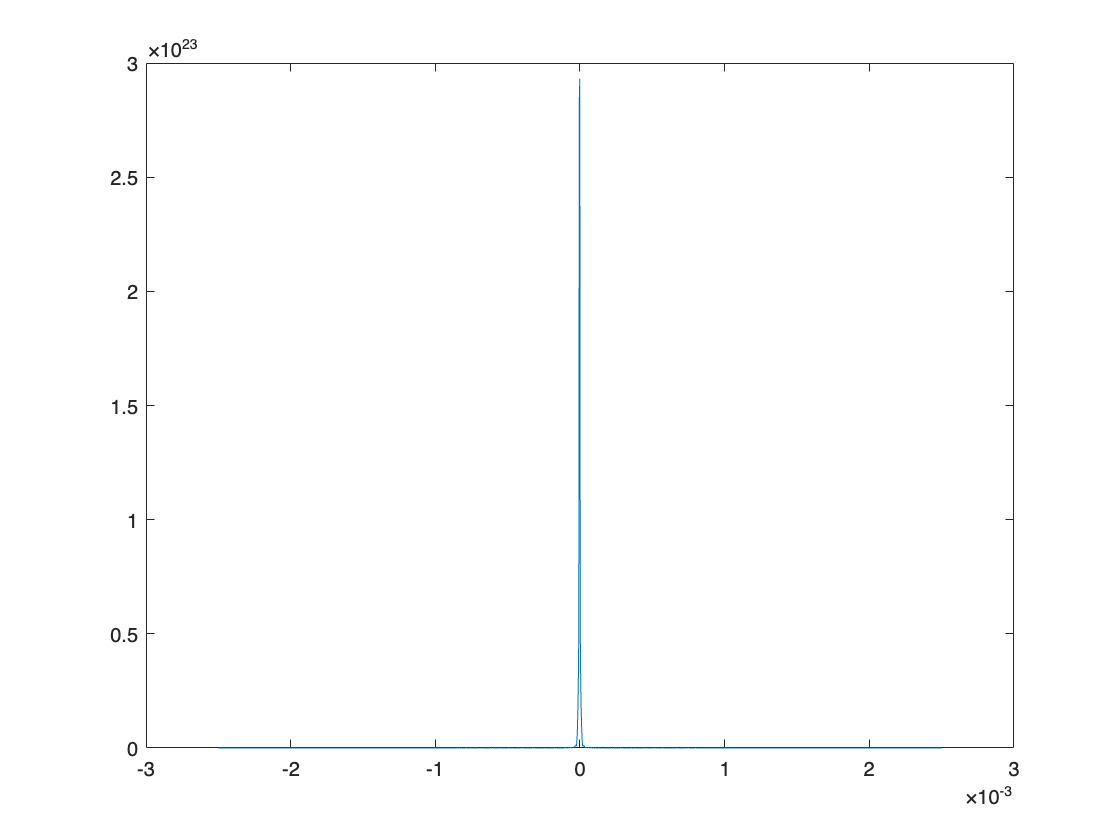

% Spherical illumination
obj_in = obj_in.*spherical_illum;  % the object field just after the hologram, when spherical illumination is used

% 1D field propagation
[PSF, sensor, X_u] = propagateField_PWD(obj_in, lambda, X_x, N, eye_loc, z_f, D_eye);

% Plot the PSF samples
plot(sensor, PSF)

% ADD YOUR CODE HERE

## Analysis of results

MTF = abs(fftshift(fft(PSF))) / sum(PSF); % (normalized) MTF as a function spatial frequency

% Spatial frequency at which the MTF is to be evaluated
mtf_freq_c = 15; % cpd
mtf_freq_range = mtf_freq_c + [-0.5 0.5]*mtf_freq_c/4; % cpd (a small range of frequencies)

ind = round(length(MTF)/2+ length(MTF)/2 * 2*X_u./(2*tand(0.5)*25e-3./mtf_freq_range)); % indices corresponding to the frequency range
mtf_at_freq_c = mean(MTF(ind(1):ind(2))); % integrated over a small range around the exact frequency

% TASK:
% The variable mtf_at_freq_c contains a single value. Repeat the simulations
% for different z_f values, fit a function to the data points and plot the
% results (see more details in the instructions). You can change the code
% to do the repetition for you.
z_f_s = [-0.5:0.01:-0.3]

z_f_s =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000


MTF_s = []


MTF_s =

     []



figure; hold on
legend_labels = cell(length(z_f_s), 1);
for i = 1:length(z_f_s)
    zz = z_f_s(i);
    legend_labels{i} = [num2str(zz)];
    [PSF, sensor, X_u] = propagateField_PWD(obj_in, lambda, X_x, N, eye_loc, zz, D_eye);
    plot(sensor, PSF, 'Color', [rand,rand,rand]); hold on
    MTF = abs(fftshift(fft(PSF))) / sum(PSF); % (normalized) MTF as a function spatial frequency
    % Spatial frequency at which the MTF is to be evaluated
    mtf_freq_c = 15; % cpd
    mtf_freq_range = mtf_freq_c + [-0.5 0.5]*mtf_freq_c/4; % cpd (a small range of frequencies)

    ind = round(length(MTF)/2+ length(MTF)/2 * 2*X_u./(2*tand(0.5)*25e-3./mtf_freq_range)); % indices corresponding to the frequency range
    mtf_at_freq_c = mean(MTF(ind(1):ind(2)))
    MTF_s = [MTF_s, mtf_at_freq_c];
end

mtf_at_freq_c = 0.3306

mtf_at_freq_c = 0.3195

mtf_at_freq_c = 0.2388

mtf_at_freq_c = 0.0938

mtf_at_freq_c = 0.1655

mtf_at_freq_c = 0.4345

mtf_at_freq_c = 0.6612

mtf_at_freq_c = 0.7689

mtf_at_freq_c = 0.7754

mtf_at_freq_c = 0.7539

mtf_at_freq_c = 0.6614

mtf_at_freq_c = 0.4587

mtf_at_freq_c = 0.2187

mtf_at_freq_c = 0.0769

mtf_at_freq_c = 0.0413

mtf_at_freq_c = 0.0236

mtf_at_freq_c = 0.0444

mtf_at_freq_c = 0.0796

mtf_at_freq_c = 0.0362

mtf_at_freq_c = 0.0338

mtf_at_freq_c = 0.0376

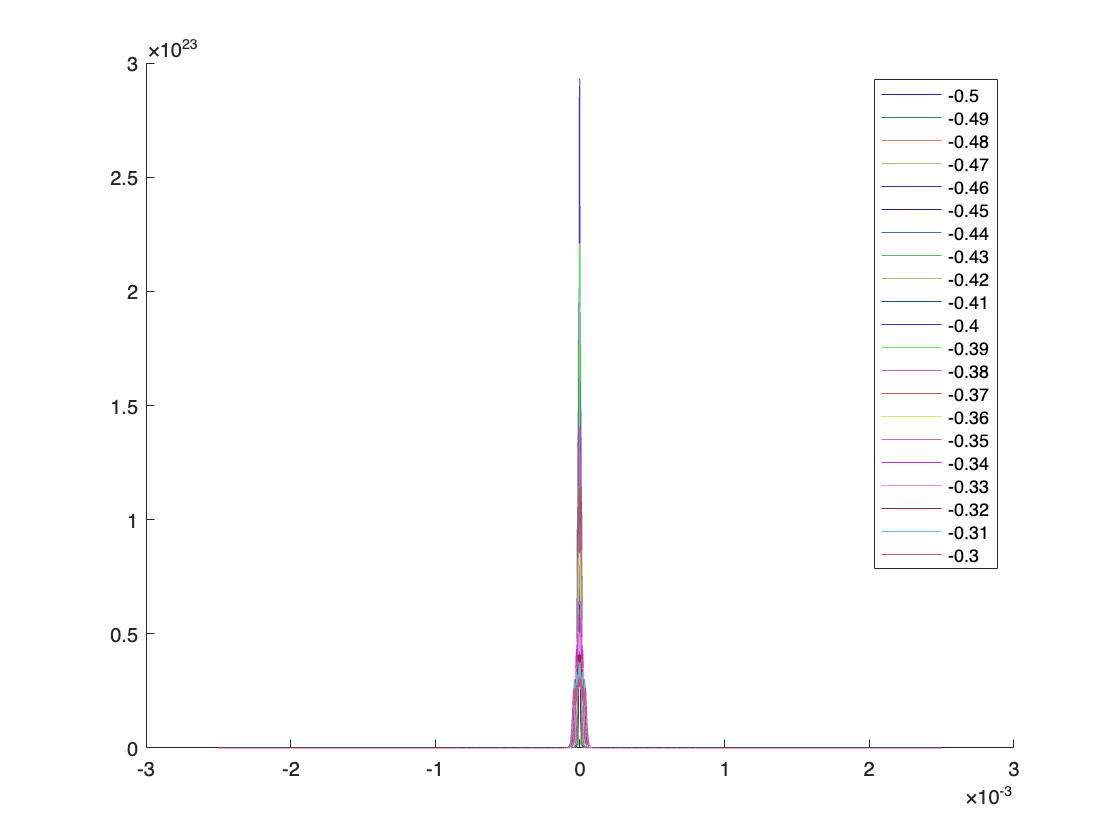

legend(legend_labels)
hold off

f = fit(z_f_s.', MTF_s.', 'poly7')

f =      Linear model Poly7:
     f(x) = p1*x^7 + p2*x^6 + p3*x^5 + p4*x^4 + p5*x^3 + 
                    p6*x^2 + p7*x + p8
     Coefficients (with 95% confidence bounds):
       p1 =   6.186e+07  (4.665e+07, 7.707e+07)
       p2 =   1.714e+08  (1.289e+08, 2.14e+08)
       p3 =   2.023e+08  (1.514e+08, 2.532e+08)
       p4 =   1.318e+08  (9.818e+07, 1.654e+08)
       p5 =   5.116e+07  (3.792e+07, 6.44e+07)
       p6 =   1.184e+07  (8.723e+06, 1.496e+07)
       p7 =   1.513e+06  (1.107e+06, 1.918e+06)
       p8 =    8.23e+04  (5.981e+04, 1.048e+05)

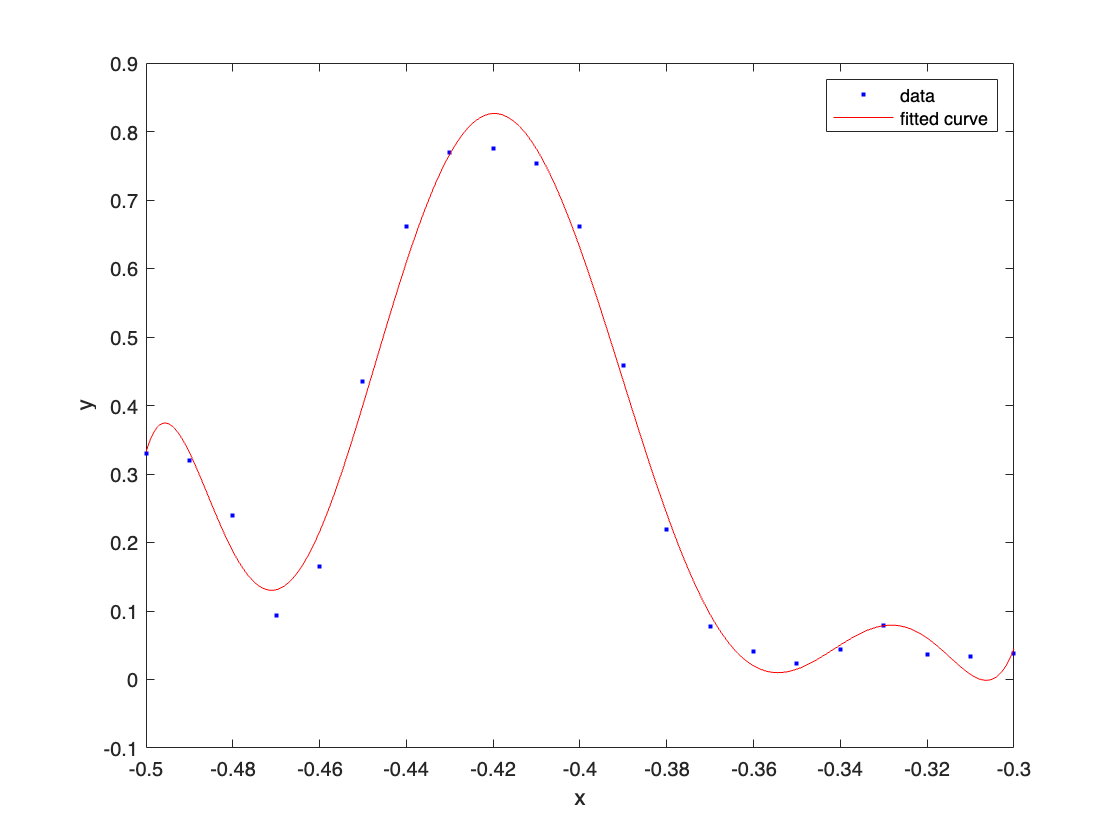

plot(f, z_f_s.', MTF_s.')

lx = [-0.5:0.001:-0.3]

lx =    -0.5000   -0.4990   -0.4980   -0.4970   -0.4960   -0.4950   -0.4940   -0.4930   -0.4920   -0.4910   -0.4900   -0.4890   -0.4880   -0.4870   -0.4860   -0.4850   -0.4840   -0.4830   -0.4820   -0.4810   -0.4800   -0.4790   -0.4780   -0.4770   -0.4760   -0.4750   -0.4740   -0.4730   -0.4720   -0.4710   -0.4700   -0.4690   -0.4680   -0.4670   -0.4660   -0.4650   -0.4640   -0.4630   -0.4620   -0.4610   -0.4600   -0.4590   -0.4580   -0.4570   -0.4560   -0.4550   -0.4540   -0.4530   -0.4520   -0.4510


A = f(lx'); % Create a column array
[maxValue, maxIndex] = max(A)

maxValue = 0.8262

maxIndex = 81

max_z = lx(maxIndex)

max_z = -0.4200